## **National Institute for Astrophysics, Optics, and Electronics**

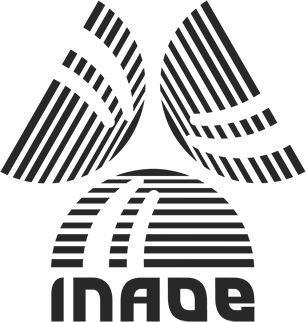

### **MSc. Science & Technology of Space**

# **Traditional Data Augmentation**

**Jorge Alberto Prado Herrada**

                                           ***                   Spring 2023***

This program performs rotation, translation, scaling, reflection or mirroring, shear, and three different synthetic noise forms of data augmentation (salt and pepper, gaussian noise and blur) in a specific folder. It works as is with .jpg files but you can easily modify it. To visualize your original data you can uncomment lines 11 & 12. 

ImgFolder = 'C:/Users/../yourImagefolder'

ImgFolder = 'C:\Users\jorge\Downloads\COBB 500\training'


% you can change image format here    v
filePattern = fullfile(ImgFolder, '*.jpg');

jpgFiles = dir(filePattern);

for k = 1:length(jpgFiles)
  baseFileName = jpgFiles(k).name;
  fullFileName = fullfile(ImgFolder, baseFileName);
  fprintf(1, 'Now reading %s\n', fullFileName);
  imageArray = imread(fullFileName);
  %imshow(imageArray);  % Display image.
  %drawnow; % Force display to update immediately.


  %% rotation   R

  tform = randomAffine2d(Rotation=[-45 45]); 
  outputView = affineOutputView(size(imageArray),tform);
  imAugmented = imwarp(imageArray,tform,OutputView=outputView);  

  rotatedFileName = sprintf('%s_rotated.jpg', baseFileName);
  newRotatedFileName = fullfile(ImgFolder, rotatedFileName);
  imwrite(imAugmented, newRotatedFileName);

  %% translation    T

  tform = randomAffine2d(XTranslation=[-50 50],YTranslation=[-50 50]);
  outputView = affineOutputView(size(imageArray),tform);
  imAugmented = imwarp(imageArray,tform,OutputView=outputView);
  
  translatedFileName = sprintf('%s_translated.jpg', baseFileName);
  newTranslatedFileName = fullfile(ImgFolder, translatedFileName);
  imwrite(imAugmented, newTranslatedFileName);
    
  %% scale  Sc

  tform = randomAffine2d(Scale=[1.2,1.5]);
  outputView = affineOutputView(size(imageArray),tform);
  imAugmented = imwarp(imageArray,tform,OutputView=outputView);
  
  scaledFileName = sprintf('%s_scaled.jpg', baseFileName);
  newScaledFileName = fullfile(ImgFolder, scaledFileName);
  imwrite(imAugmented, newScaledFileName);

  %% reflection/mirror M

  tform = randomAffine2d(XReflection=true,YReflection=true);
  outputView = affineOutputView(size(imageArray),tform);
  imAugmented = imwarp(imageArray,tform,OutputView=outputView);

  mirrorFileName = sprintf('%s_mirrored.jpg', baseFileName);
  newMirrorFileName = fullfile(ImgFolder, mirrorFileName);
  imwrite(imAugmented, newMirrorFileName);

  %% shear  Sh

  tform = randomAffine2d(XShear=[-30 30]); 
  outputView = affineOutputView(size(imageArray),tform); 
  imAugmented = imwarp(imageArray,tform,OutputView=outputView);
  

  shearFileName = sprintf('%s_sheared.jpg', baseFileName);
  newShearFileName = fullfile(ImgFolder, shearFileName);
  imwrite(imAugmented, newShearFileName);

  %% synthetic noise & blur
  % salt pepper

  imSaltAndPepperNoise = imnoise(imageArray,"salt & pepper",0.1);
 
  spFileName = sprintf('%s_sp.jpg', baseFileName);
  newSPFileName = fullfile(ImgFolder, spFileName);
  imwrite(imSaltAndPepperNoise, newSPFileName);

  % gaussian noise

  imGaussianNoise = imnoise(imageArray,"gaussian");

  gaussFileName = sprintf('%s_gauss.jpg', baseFileName);
  newGaussFileName = fullfile(ImgFolder, gaussFileName);
  imwrite(imGaussianNoise, newGaussFileName);  

  %blur

  sigma = 1+5*rand; 
  imBlurred = imgaussfilt(imageArray,sigma); 

  blurFileName = sprintf('%s_blurred.jpg', baseFileName);
  newBlurFileName = fullfile(ImgFolder, blurFileName);
  imwrite(imBlurred, newBlurFileName);

end

spFileName = 'DSC03854.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03854.JPG_sp.jpg'

gaussFileName = 'DSC03854.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03854.JPG_gauss.jpg'

blurFileName = 'DSC03854.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03854.JPG_blurred.jpg'

spFileName = 'DSC03856.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03856.JPG_sp.jpg'

gaussFileName = 'DSC03856.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03856.JPG_gauss.jpg'

blurFileName = 'DSC03856.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03856.JPG_blurred.jpg'

spFileName = 'DSC03862.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03862.JPG_sp.jpg'

gaussFileName = 'DSC03862.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03862.JPG_gauss.jpg'

blurFileName = 'DSC03862.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03862.JPG_blurred.jpg'

spFileName = 'DSC03893.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03893.JPG_sp.jpg'

gaussFileName = 'DSC03893.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03893.JPG_gauss.jpg'

blurFileName = 'DSC03893.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03893.JPG_blurred.jpg'

spFileName = 'DSC03924.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03924.JPG_sp.jpg'

gaussFileName = 'DSC03924.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03924.JPG_gauss.jpg'

blurFileName = 'DSC03924.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03924.JPG_blurred.jpg'

spFileName = 'DSC03946.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03946.JPG_sp.jpg'

gaussFileName = 'DSC03946.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03946.JPG_gauss.jpg'

blurFileName = 'DSC03946.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03946.JPG_blurred.jpg'

spFileName = 'DSC03947.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03947.JPG_sp.jpg'

gaussFileName = 'DSC03947.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03947.JPG_gauss.jpg'

blurFileName = 'DSC03947.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03947.JPG_blurred.jpg'

spFileName = 'DSC03948.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03948.JPG_sp.jpg'

gaussFileName = 'DSC03948.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03948.JPG_gauss.jpg'

blurFileName = 'DSC03948.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03948.JPG_blurred.jpg'

spFileName = 'DSC03949.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03949.JPG_sp.jpg'

gaussFileName = 'DSC03949.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03949.JPG_gauss.jpg'

blurFileName = 'DSC03949.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03949.JPG_blurred.jpg'

spFileName = 'DSC03950.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03950.JPG_sp.jpg'

gaussFileName = 'DSC03950.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03950.JPG_gauss.jpg'

blurFileName = 'DSC03950.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03950.JPG_blurred.jpg'

spFileName = 'DSC03951.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03951.JPG_sp.jpg'

gaussFileName = 'DSC03951.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03951.JPG_gauss.jpg'

blurFileName = 'DSC03951.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03951.JPG_blurred.jpg'

spFileName = 'DSC03952.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03952.JPG_sp.jpg'

gaussFileName = 'DSC03952.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03952.JPG_gauss.jpg'

blurFileName = 'DSC03952.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03952.JPG_blurred.jpg'

spFileName = 'DSC03953.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03953.JPG_sp.jpg'

gaussFileName = 'DSC03953.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03953.JPG_gauss.jpg'

blurFileName = 'DSC03953.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03953.JPG_blurred.jpg'

spFileName = 'DSC03954.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03954.JPG_sp.jpg'

gaussFileName = 'DSC03954.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03954.JPG_gauss.jpg'

blurFileName = 'DSC03954.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03954.JPG_blurred.jpg'

spFileName = 'DSC03955.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03955.JPG_sp.jpg'

gaussFileName = 'DSC03955.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03955.JPG_gauss.jpg'

blurFileName = 'DSC03955.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03955.JPG_blurred.jpg'

spFileName = 'DSC03956.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03956.JPG_sp.jpg'

gaussFileName = 'DSC03956.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03956.JPG_gauss.jpg'

blurFileName = 'DSC03956.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03956.JPG_blurred.jpg'

spFileName = 'DSC03957.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03957.JPG_sp.jpg'

gaussFileName = 'DSC03957.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03957.JPG_gauss.jpg'

blurFileName = 'DSC03957.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03957.JPG_blurred.jpg'

spFileName = 'DSC03958.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03958.JPG_sp.jpg'

gaussFileName = 'DSC03958.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03958.JPG_gauss.jpg'

blurFileName = 'DSC03958.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03958.JPG_blurred.jpg'

spFileName = 'DSC03959.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03959.JPG_sp.jpg'

gaussFileName = 'DSC03959.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03959.JPG_gauss.jpg'

blurFileName = 'DSC03959.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03959.JPG_blurred.jpg'

spFileName = 'DSC03960.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03960.JPG_sp.jpg'

gaussFileName = 'DSC03960.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03960.JPG_gauss.jpg'

blurFileName = 'DSC03960.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03960.JPG_blurred.jpg'

spFileName = 'DSC03964.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03964.JPG_sp.jpg'

gaussFileName = 'DSC03964.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03964.JPG_gauss.jpg'

blurFileName = 'DSC03964.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03964.JPG_blurred.jpg'

spFileName = 'DSC03967.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03967.JPG_sp.jpg'

gaussFileName = 'DSC03967.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03967.JPG_gauss.jpg'

blurFileName = 'DSC03967.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03967.JPG_blurred.jpg'

spFileName = 'DSC03970.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03970.JPG_sp.jpg'

gaussFileName = 'DSC03970.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03970.JPG_gauss.jpg'

blurFileName = 'DSC03970.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03970.JPG_blurred.jpg'

spFileName = 'DSC03976.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03976.JPG_sp.jpg'

gaussFileName = 'DSC03976.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03976.JPG_gauss.jpg'

blurFileName = 'DSC03976.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03976.JPG_blurred.jpg'

spFileName = 'DSC03979.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03979.JPG_sp.jpg'

gaussFileName = 'DSC03979.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03979.JPG_gauss.jpg'

blurFileName = 'DSC03979.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC03979.JPG_blurred.jpg'

spFileName = 'DSC04051.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04051.JPG_sp.jpg'

gaussFileName = 'DSC04051.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04051.JPG_gauss.jpg'

blurFileName = 'DSC04051.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04051.JPG_blurred.jpg'

spFileName = 'DSC04052.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04052.JPG_sp.jpg'

gaussFileName = 'DSC04052.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04052.JPG_gauss.jpg'

blurFileName = 'DSC04052.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04052.JPG_blurred.jpg'

spFileName = 'DSC04053.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04053.JPG_sp.jpg'

gaussFileName = 'DSC04053.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04053.JPG_gauss.jpg'

blurFileName = 'DSC04053.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04053.JPG_blurred.jpg'

spFileName = 'DSC04054.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04054.JPG_sp.jpg'

gaussFileName = 'DSC04054.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04054.JPG_gauss.jpg'

blurFileName = 'DSC04054.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04054.JPG_blurred.jpg'

spFileName = 'DSC04055.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04055.JPG_sp.jpg'

gaussFileName = 'DSC04055.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04055.JPG_gauss.jpg'

blurFileName = 'DSC04055.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04055.JPG_blurred.jpg'

spFileName = 'DSC04056.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04056.JPG_sp.jpg'

gaussFileName = 'DSC04056.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04056.JPG_gauss.jpg'

blurFileName = 'DSC04056.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04056.JPG_blurred.jpg'

spFileName = 'DSC04057.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04057.JPG_sp.jpg'

gaussFileName = 'DSC04057.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04057.JPG_gauss.jpg'

blurFileName = 'DSC04057.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04057.JPG_blurred.jpg'

spFileName = 'DSC04058.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04058.JPG_sp.jpg'

gaussFileName = 'DSC04058.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04058.JPG_gauss.jpg'

blurFileName = 'DSC04058.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04058.JPG_blurred.jpg'

spFileName = 'DSC04059.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04059.JPG_sp.jpg'

gaussFileName = 'DSC04059.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04059.JPG_gauss.jpg'

blurFileName = 'DSC04059.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04059.JPG_blurred.jpg'

spFileName = 'DSC04060.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04060.JPG_sp.jpg'

gaussFileName = 'DSC04060.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04060.JPG_gauss.jpg'

blurFileName = 'DSC04060.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04060.JPG_blurred.jpg'

spFileName = 'DSC04061.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04061.JPG_sp.jpg'

gaussFileName = 'DSC04061.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04061.JPG_gauss.jpg'

blurFileName = 'DSC04061.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04061.JPG_blurred.jpg'

spFileName = 'DSC04062.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04062.JPG_sp.jpg'

gaussFileName = 'DSC04062.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04062.JPG_gauss.jpg'

blurFileName = 'DSC04062.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04062.JPG_blurred.jpg'

spFileName = 'DSC04063.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04063.JPG_sp.jpg'

gaussFileName = 'DSC04063.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04063.JPG_gauss.jpg'

blurFileName = 'DSC04063.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04063.JPG_blurred.jpg'

spFileName = 'DSC04064.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04064.JPG_sp.jpg'

gaussFileName = 'DSC04064.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04064.JPG_gauss.jpg'

blurFileName = 'DSC04064.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04064.JPG_blurred.jpg'

spFileName = 'DSC04065.JPG_sp.jpg'

newSPFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04065.JPG_sp.jpg'

gaussFileName = 'DSC04065.JPG_gauss.jpg'

newGaussFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04065.JPG_gauss.jpg'

blurFileName = 'DSC04065.JPG_blurred.jpg'

newBlurFileName = 'C:\Users\jorge\Downloads\COBB 500\training\DSC04065.JPG_blurred.jpg'